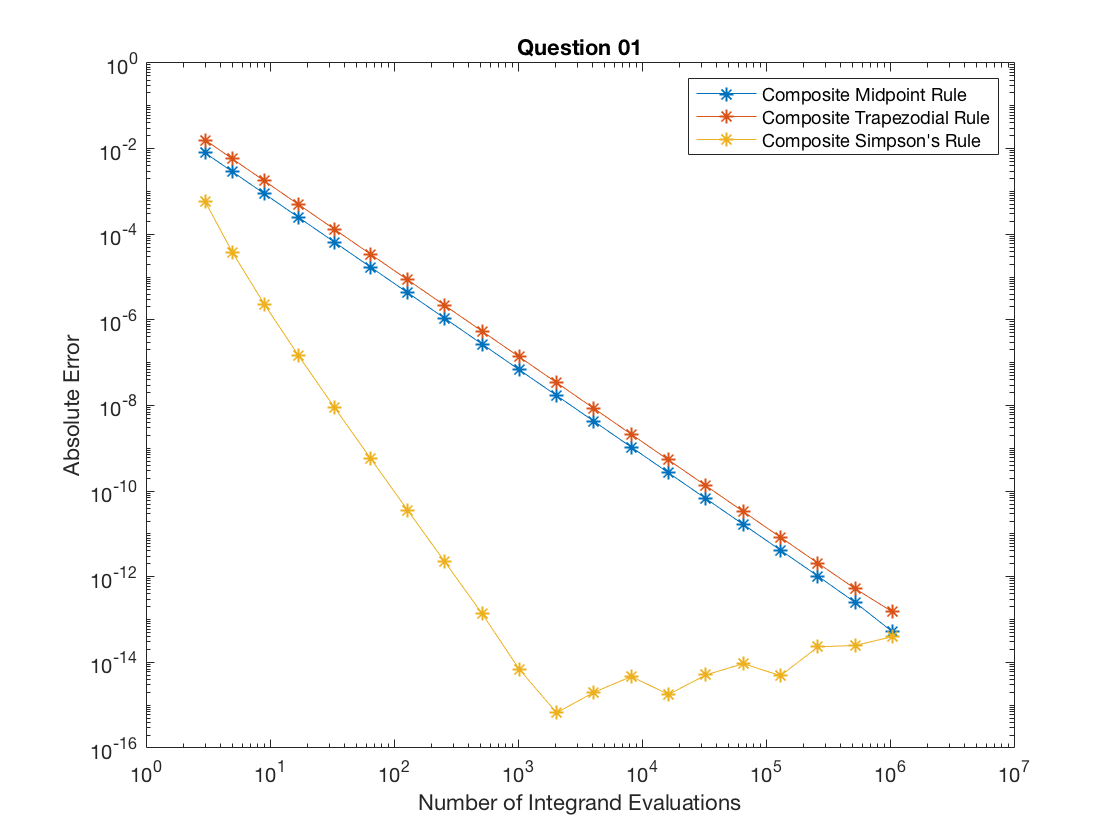

%Number 1
f = @(x) exp(x);
a = 0;
b = 1;

% Exact Value
exact = integral(f,a,b);

for k = 1:20
    n(k) = 2^k+1;
    %Estimation
    midpoint_estimation = midpoint(f,a,b,n(k));
    trap_estimation = trapazodial(f,a,b,n(k));
    simpson_estimation= simpsons(f,a,b,n(k));
    
    % Abs = Estimation - Exact
    midpointError(k) = abs(exact - midpoint_estimation);
    trapError(k) = abs(exact - trap_estimation);
    simpsonError(k) = abs(exact - simpson_estimation);
end

%Graph Making
loglog(n,midpointError,'-*',n,trapError,'-*',n,simpsonError,'-*');
title('Question 01');
legend("Composite Midpoint Rule","Composite Trapezodial Rule","Composite Simpson's Rule");
ylabel('Absolute Error');
xlabel('Number of Integrand Evaluations');

% Number 2
% Exact value is 1.7183
exact = integral(f,a,b);

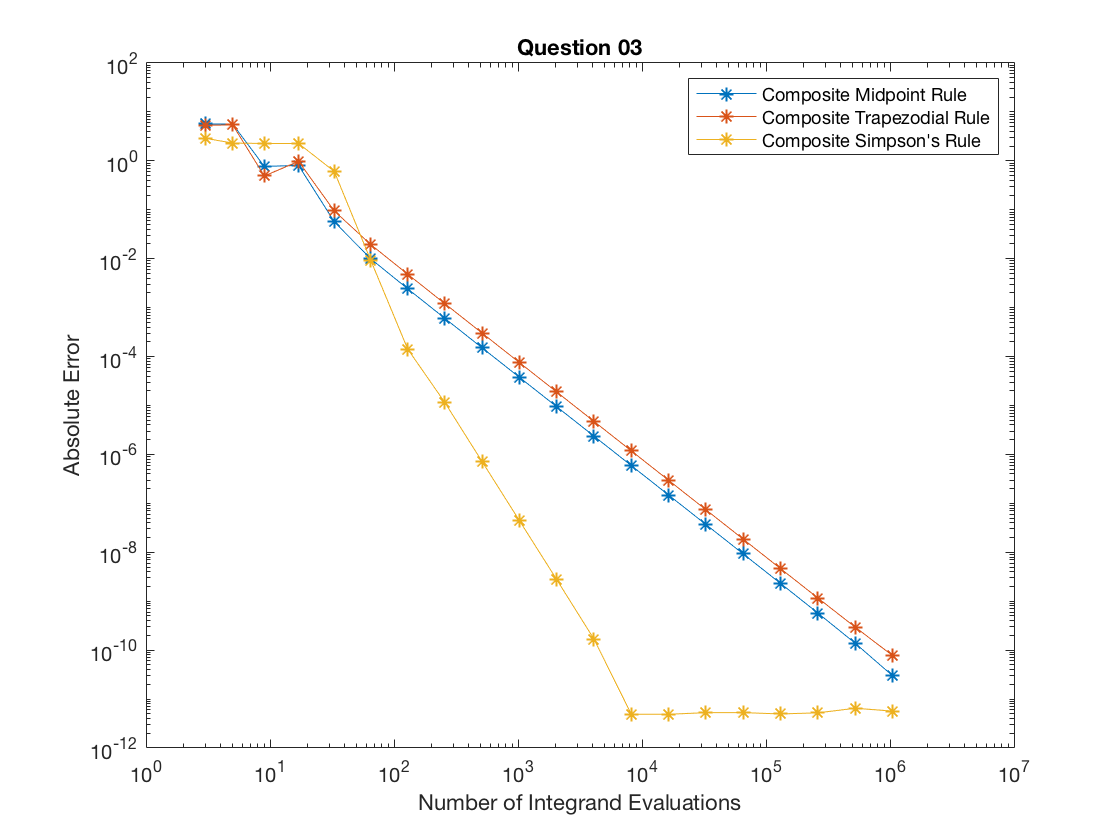

% Number 3
f = @(x) sqrt(1+cos(x).^2);
a = 0;
b = 48;

% Exact Value
exact = integral(f,a,b);

for k = 1:20
    n(k) = 2^k+1;
    %Estimation
    midpoint_estimation = midpoint(f,a,b,n(k));
    trap_estimation = trapazodial(f,a,b,n(k));
    simpson_estimation= simpsons(f,a,b,n(k));
    
    % Abs = Estimation - Exact
    midpointError(k) = abs(exact - midpoint_estimation);
    trapError(k) = abs(exact - trap_estimation);
    simpsonError(k) = abs(exact - simpson_estimation);
end

%Graph Making
loglog(n,midpointError,'-*',n,trapError,'-*',n,simpsonError,'-*');
legend("Composite Midpoint Rule","Composite Trapezodial Rule","Composite Simpson's Rule");
ylabel('Absolute Error');
xlabel('Number of Integrand Evaluations');
title('Question 03');

function val = simpsons(f,a,b,n)
%f=function for which integration have to do
%a=upper limit of integration
%b=lower limit of integration
%n=number of subintervals
h=(b-a)/(n-1);
x=linspace(a,b,n);
y=0;
for i = 1:(numel(x)-1)/2
    y = y + f(x(2*i-1)) + 4*f(x(2*i)) + f(x(2*i+1));
end
val=(h/3)*y;
end

function val = trapazodial(f,a,b,n)
% f is the function for integration
% a is the lower limit of integration
% b is the upper limit of integration
% n is the number of trapizoidal interval in [a,b]
h=(b-a)/n; %x interval
val=0;
xx=linspace(a,b,n+1);
%loop for trapizoidal integration
for i=2:n
    val=val+2*double(f(xx(i)));
end
val=(h/2)*(val+f(a)+f(b));
end

function val = midpoint(f,a,b,n)
% f is the function for integration
% a is the lower limit of integration
% b is the upper limit of integration
% n is the number of trapizoidal interval in [a,b]
dx=(b-a)/n; %x interval
val=0;
x=linspace(a,b,n+1);
for i=1:n
    x_mid(i)=(x(i+1)+x(i))/2;
    val=val+double(f(x_mid(i)));
end
val=dx*val;
end
